%% Script Information

% Name           : AUV_compare
% Description    : This document corresponds to the first subsection 
%                 "Comparison on control performance" of section "Result"
% Version        : 1
% Original author: Yu Shenhan, Jiangnan University
% Original date  : 2025.1.18

% There are too many outputs including constants, matrixs and vectors. But many of them are Intermediate
% variables, the important ones are "Error_SMC_state", "Error_lqr_state", "Error_COC_state", "F_SMC_state", 
% "F_lqr_state", "F_COC_state", "Error_COC_xr_state", "J_SMC_State", "J_lqr_State", "J_COC_State". These 
% variables can be seperated into four groups. 
% The first group ("Error_SMC_state", "Error_lqr_state", "Error_COC_state") contributes to Fig. 3, which shows 
% the state responses of UUV under the control of LQR, SMC and COC. 
% The second group ("Error_COC_xr_state") contributes to Fig. 4, which compares the proportion of 
% sub-deviations from thruster noise and current disturbance in the total deviation of UUV under current 
% disturbance. 
% The third group ("F_SMC_state", "F_lqr_state", "F_COC_state") contributes to Fig. 5, which shows thrust 
% changing lines of each thruster. 
% The last group ("J_SMC_State", "J_lqr_State", "J_COC_State") provides the corresponding data for Figure 6.
% 
% To obtain these four groups of variables, readers only need to open "AUV_compare.mlx" in Matlab version 
% 2022a and above and set the current folder to "Comparison_under_current_disturbance" folder. Then click 
% the RUN button, wait a few minutes, the figures will be shown in each subsections.

clc
clear
echo on
echo off 
disp('Simulating  ...')

Simulating  ...


% Initial value setting

gray=[0.38 0.38 0.38];
white = [1 1 1];

%x = [ x; y; z; ph; th; ps; u; v; w;  p;  q;  r ]
s_freq = 1;      % Hz
s_time = 1/s_freq; % sec

v_cable = 1/40; % Speed of releasing optical cables

Sea_density = 1;    % Average density of ocean
g_equivalent = 9.8 - Sea_density;

%F_rope_flag = [K;alpha;Sea_density;C_f;d;M_oc]
%Normalization coefficient; Cable inclination
height_norm = 1;    % Normalization coefficient
alpha = pi/6;   % Cable inclination
C_f = 0.35; % Friction coefficient between the optical cable and the seabed
d = 0.003;  % Cable diameter
M_oc = 0.001;   % Cable quality

Wave_basic = [1;1;1];   % Current direction
Wave_basic = 1 .* Wave_basic/norm(Wave_basic) * Sea_density;

Wave_gain = 1;  % Current speed
Wave_fre = 100; % Current frequency
Wave_phase = 0; % Current Angle

cable_base_mass = 5;    % Optical cable base quality

Tasktime_1 = 2000;  % Task time setting

% Initialization section

Desired_eta_state = [];

Mv_pack = cell(3,1);
Dv_pack = cell(3,1);
Cv_pack = cell(3,1);
gv_pack = cell(3,1);
J_pack = cell(3,1);
J_pack{1,1} = zeros(6,6);
Disturbance_estimated = zeros(6,1);
P = zeros(6,1);

State_pree = zeros(12,1);
State_pre = zeros(12,1);
State = zeros(12,1);
Desired_eta_pree = zeros(6,1);
Desired_eta_pre = zeros(6,1);
Desired_eta = zeros(6,1);
cable_mass_pre = 0;

Ui_COC = zeros(6,1);
L_det_state = [];

Ui_lqr_state = [];
Ui_SMC_state = [];
Ui_COC_state = [];

F_lqr_state = [];
F_SMC_state = [];
F_COC_state = [];

Error_lqr_state = [];
Error_SMC_state = [];
Error_COC_state = [];

% Starting position                        
Initial_x = [ 45; 45; 110;   0; 0; 0;   1; 1; 1; 0; 0; 0];

% Hover position
Start_point = [ 50; 50; 100;   0; 0; 0;   0; 0; 0; 0; 0; 0];

% Planning section

Initial_x_tra = eul2rotm(Initial_x(4:6).');
Initial_x_tra = RpToTrans(Initial_x_tra, Initial_x(1:3));

Start_point_tra = eul2rotm(Start_point(4:6).');
Start_point_tra = RpToTrans(Start_point_tra, Start_point(1:3));

%main loop

xout_lqr = zeros(Tasktime_1-1,length(Initial_x)+1);
xout_SMC = zeros(Tasktime_1-1,length(Initial_x)+1);
xout_COC = zeros(Tasktime_1-1,length(Initial_x)+1);
State_lqr=Initial_x; State_SMC=Initial_x; State_COC=Initial_x; Error_COC = zeros(12,1);
J_COC_preState = []; L_preState = []; J_LQR_State = []; J_SMC_State = []; J_COC_State = [];
L_det_state = []; K_co_state = []; Wave_state = [];

model_information_lqr = cell(8,1);
model_information_SMC = cell(8,1);
model_information_COC = cell(8,1);
model_information_COC_linear = cell(6,1);

[R_lqr,Q_lqr,Q,R,R_SMC,L_standard,switch_gain] = control_parameter;

Ui = zeros(12,1);
gamma = 1;

[A,B2,B1,C1,D12,D11] = Find_AB(Start_point,Ui,Wave_basic);
[model_information_COC_linear] = model_pack(A,B2,B1,C1,D12,D11);
[Ko,Po,Kr_optimal,Kr_suboptimal,root1,root2_optimal,root2_suboptimal] = Get_control_gain(A,B2,B1,C1,D12,D11,gamma,Q_lqr,R_lqr);


 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1                   0.834586
     2                   0.156406
     3                   0.156406
     4                   0.050633
     5                   0.050633
     6                   0.025532
     7                   0.025532
     8                   0.011466
     9                   0.011466
    10               7.779124e-03
    11               7.779124e-03
    12               3.692274e-03
    13               3.692274e-03
    14               2.747526e-03
    15               2.747526e-03
    16               1.469911e-03
    17               1.469911e-03
    18               1.469911e-03
    19               1.469911e-03
    20               1.469911e-03
    21               1.127622e-03
    22               1.127622e-03
    23               1.127622e-03
    24               9.884156e-04
    25               6.843855e-04
    26               1.097008e-04

% Ocean current interference signal generation
Wave_Fs=1;
Wave_T=2000;
Wave_dt=1.0/Wave_Fs;
Wave_N=Wave_T/Wave_dt;
Wave_t=linspace(0, Wave_T, Wave_N);
Wave_state_basic= 1 * sin(2*pi* 5 *Wave_t);

for i=1:Tasktime_1-1
    i=i+1;

    Wave_state = importdata("wave_state.mat");
    Wave = Wave_state(:,i-1);

    time = (i-1)*s_time;

    Desired_eta_pree = Desired_eta_pre;
    Desired_eta_pre = Desired_eta;
    Desired_eta = Start_point;
    Desired_eta_state = [Desired_eta_state,Desired_eta];

    mass_loss = cable_mass_pre;
    mass_loss_1 = mass_loss;
    time_flag = [Tasktime_1,i,M_oc,cable_base_mass,v_cable,g_equivalent,cable_mass_pre,mass_loss];
    F_rope_flag = [height_norm;alpha;Sea_density;C_f;d;M_oc];
    [model_information_lqr] = Get_real_model_compare(1,State_lqr,Wave,time_flag,F_rope_flag);
    [model_information_SMC] = Get_real_model_compare(1,State_SMC,Wave,time_flag,F_rope_flag);
    [model_information_COC] = Get_real_model_compare(1,State_COC,Wave,time_flag,F_rope_flag);

    %Error
    Error_lqr = State_lqr - Desired_eta;
    Error_lqr_state = [Error_lqr_state, Error_lqr];

    Error_SMC = State_SMC - Desired_eta;
    Error_SMC_state = [Error_SMC_state, Error_SMC];

    Error_COC_pre = Error_COC;
    Error_COC = State_COC - Desired_eta;
    Error_COC_state = [Error_COC_state, Error_COC];
    COC_flag{1,1} = Error_COC; COC_flag{2,1} = Error_COC_pre; COC_flag{3,1} = J_COC_preState;
    COC_flag{4,1} = L_preState;

    Ui_lqr = -Ko*Error_lqr;
    Ui_lqr_state = [Ui_lqr_state, Ui_lqr];

    %SMC
    [Ui_SMC] = SMC(State_SMC,Error_SMC,model_information_SMC,switch_gain,R_SMC);
    Ui_SMC_state = [Ui_SMC_state, Ui_SMC];

    %COC
    [Ui_COC,J_COC_preState,L_preState,L_det,K_co] = COC(Ui_COC,model_information_COC_linear,COC_flag,Ko,Po,State_COC,model_information_COC,L_det_state,Q,R,L_standard,switch_gain,R_SMC);
    Ui_COC_state = [Ui_COC_state, Ui_COC];
    L_det_state = [L_det_state, L_det];
    K_co_state = [K_co_state, K_co];

    % Thrust allocation
    F_lqr = ThrustAllocation(Ui_lqr);
    F_lqr_state = [F_lqr_state, F_lqr];

    F_SMC = ThrustAllocation(Ui_SMC);
    F_SMC_state = [F_SMC_state, F_SMC];

    F_COC = ThrustAllocation(Ui_COC);
    F_COC_state = [F_COC_state, F_COC];
    
    [t,S_list] = ode15s(@(t,State_lqr) AUV_Dynamic_model(t,State_lqr,Ui_lqr,model_information_lqr), [0  s_time], State_lqr);
    State_lqr = S_list(end,(1:12)).';
    [t,S_list] = ode15s(@(t,State_SMC) AUV_Dynamic_model(t,State_SMC,Ui_SMC,model_information_SMC), [0  s_time], State_SMC);
    State_SMC = S_list(end,(1:12)).';
    [t,S_list] = ode15s(@(t,State_COC) AUV_Dynamic_model(t,State_COC,Ui_COC,model_information_COC), [0  s_time], State_COC);
    State_COC = S_list(end,(1:12)).';

    % Output Records
    xout_lqr(i-1,:) = [i-1,State_lqr'];
    xout_SMC(i-1,:) = [i-1,State_SMC'];
    xout_COC(i-1,:) = [i-1,State_COC'];

    [J_LQR,J_SMC,J_COC] = Get_cost_function(Error_lqr, Error_SMC, Error_COC, Ui_lqr, Ui_SMC, Ui_COC,Q,R);
    J_LQR_State = [J_LQR_State J_LQR];
    J_SMC_State = [J_SMC_State J_SMC];
    J_COC_State = [J_COC_State J_COC];
end

% Extracting position and pose information

% real
xout_lqr(:,1) = [];
xout_SMC(:,1) = [];
xout_COC(:,1) = [];
xout_lqr = xout_lqr .* [1,1,1,180/pi,180/pi,180/pi,1,1,1,180/pi,180/pi,180/pi];
xout_SMC = xout_SMC .* [1,1,1,180/pi,180/pi,180/pi,1,1,1,180/pi,180/pi,180/pi];
xout_COC = xout_COC .* [1,1,1,180/pi,180/pi,180/pi,1,1,1,180/pi,180/pi,180/pi];
Desired_eta_state = Desired_eta_state .* [1;1;1;180/pi;180/pi;180/pi;1;1;1;180/pi;180/pi;180/pi];
F_SMC_state = F_SMC_state./500; F_COC_state = F_COC_state./500; F_lqr_state = F_lqr_state./500;
Error_lqr_state = Error_lqr_state .* [1;1;1;180/pi;180/pi;180/pi;1;1;1;180/pi;180/pi;180/pi];
Error_SMC_state = Error_SMC_state .* [1;1;1;180/pi;180/pi;180/pi;1;1;1;180/pi;180/pi;180/pi];
Error_COC_state = Error_COC_state .* [1;1;1;180/pi;180/pi;180/pi;1;1;1;180/pi;180/pi;180/pi];
Error_lqr_state_RMSE = RMSE(Error_lqr_state);
Error_SMC_state_RMSE = RMSE(Error_SMC_state);
Error_COC_state_RMSE = RMSE(Error_COC_state);
K_co_state_smooth = smooth(K_co_state);
Error_COC_xr_state = Error_COC_state .* K_co_state_smooth;

% Drawing part

% 3D Perspective

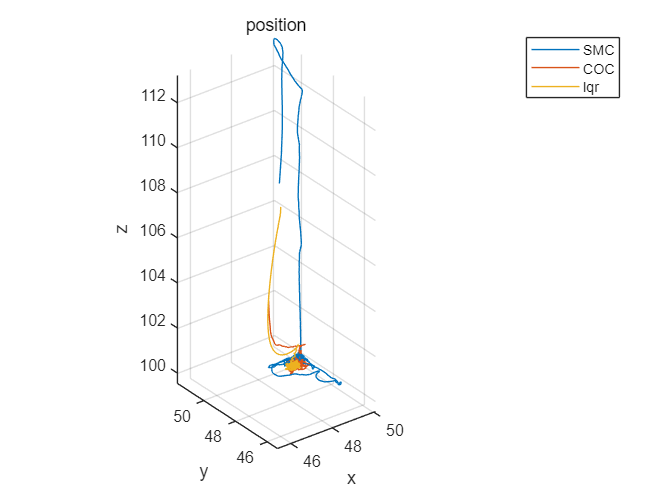

figure(1);
plot3(xout_SMC(:,1),xout_SMC(:,2),xout_SMC(:,3));
hold on;
plot3(xout_COC(:,1),xout_COC(:,2),xout_COC(:,3));
hold on;
plot3(xout_lqr(:,1),xout_lqr(:,2),xout_lqr(:,3)),grid,axis('equal'),xlabel('x'),ylabel('y'),zlabel('z'),title('position');
legend('SMC','COC','lqr');

% System deviation change curve

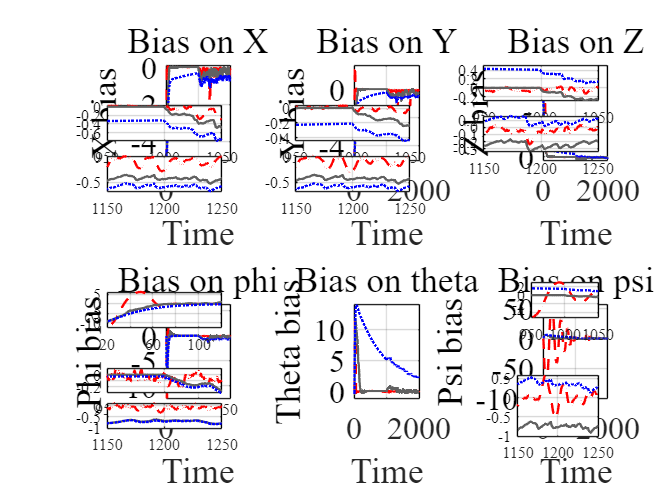

figure(1);
subplot(2,3,1);
plot(Error_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('X bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on X');

h1 = axes('Position',[0.16 0.72 0.17 0.07]);
axes(h1);
plot(Error_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[950 1050]);
set(gca,'FontName','Times New Roman');
grid on;

h7 = axes('Position',[0.16 0.62 0.17 0.07]);
axes(h7);
plot(Error_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h7,'xlim',[1150 1250]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,2);
plot(Error_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Y bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on Y');

h2 = axes('Position',[0.44 0.72 0.17 0.07]);
axes(h2);
plot(Error_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h2,'xlim',[950 1050]);
set(gca,'FontName','Times New Roman');
grid on;

h8 = axes('Position',[0.44 0.62 0.17 0.07]);
axes(h8);
plot(Error_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h8,'xlim',[1150 1250]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Error_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Z bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on Z');

h3 = axes('Position',[0.72 0.8 0.17 0.07]);
axes(h3);
plot(Error_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h3,'xlim',[950 1050]);
set(gca,'FontName','Times New Roman');
grid on;

h9 = axes('Position',[0.72 0.7 0.17 0.07]);
axes(h9);
plot(Error_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h9,'xlim',[1150 1250]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,4);
plot(Error_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Phi bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on phi');

h4 = axes('Position',[0.16 0.35 0.17 0.07]);
axes(h4);
plot(Error_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h4,'xlim',[20 120]);
set(gca,'FontName','Times New Roman');
grid on;

h10 = axes('Position',[0.16 0.22 0.17 0.05]);
axes(h10);
plot(Error_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h10,'xlim',[950 1050]);
set(gca,'FontName','Times New Roman');
grid on;

h11 = axes('Position',[0.16 0.15 0.17 0.05]);
axes(h11);
plot(Error_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h11,'xlim',[1150 1250]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,5);
plot(Error_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Theta bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on theta');

subplot(2,3,6);
plot(Error_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Psi bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on psi');

h6 = axes('Position',[0.79 0.37 0.1 0.07]);
axes(h6);
plot(Error_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h6,'xlim',[950 1050]);
set(gca,'FontName','Times New Roman');
grid on;

h12 = axes('Position',[0.77 0.135 0.12 0.12]);
axes(h12);
plot(Error_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h12,'xlim',[1150 1250]);
set(gca,'FontName','Times New Roman');
grid on;

% RMSE of system deviation

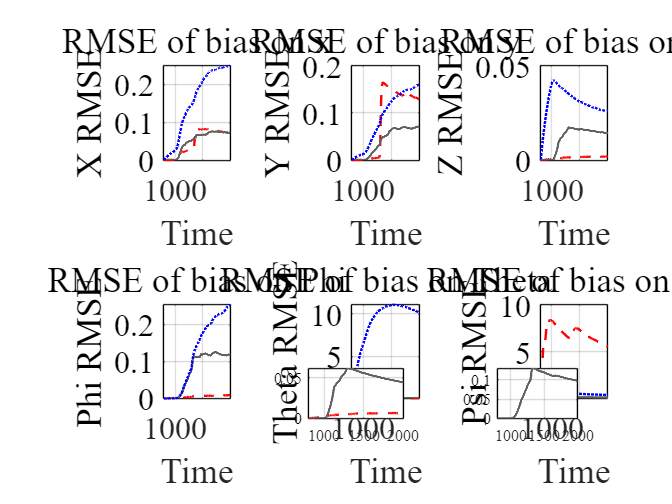

figure(2);
subplot(2,3,1);
Time = [801:2000];
plot(Time,Error_SMC_state_RMSE(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('X RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on x');

subplot(2,3,2);
plot(Time,Error_SMC_state_RMSE(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Y RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on y');

subplot(2,3,3);
plot(Time,Error_SMC_state_RMSE(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Z RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on z');

subplot(2,3,4);
plot(Time,Error_SMC_state_RMSE(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Phi RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on Phi');

subplot(2,3,5);
plot(Time,Error_SMC_state_RMSE(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Theta RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on Theta');

h5 = axes('Position',[0.46 0.17 0.14 0.1]);
axes(h5);
plot(Time,Error_SMC_state_RMSE(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(5,:),'-',Color=gray,LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,6);
plot(Time,Error_SMC_state_RMSE(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
plot(Time,Error_COC_state_RMSE(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
ylabel('Psi RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on Psi');

h6 = axes('Position',[0.74 0.17 0.12 0.1]);
axes(h6);
plot(Time,Error_COC_state_RMSE(6,:),'-',Color=gray,LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(gca,'FontName','Times New Roman');
grid on;

% Resultant force and moment

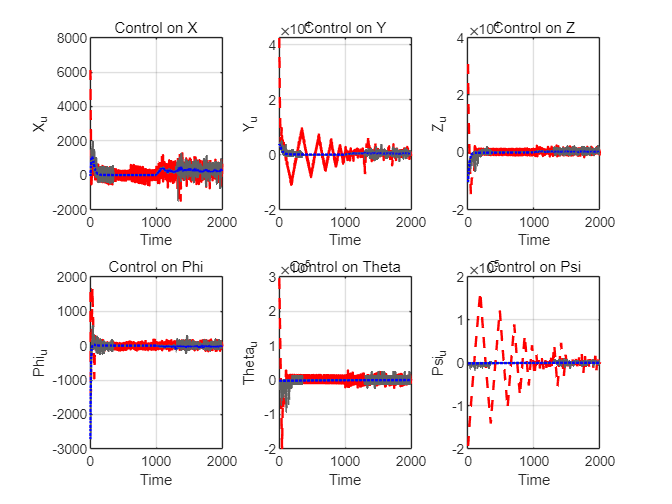

figure(3);
subplot(2,3,1);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('X_u');
xlabel('Time');
title('Control on X');

subplot(2,3,2);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Y_u');
xlabel('Time');
title('Control on Y');

subplot(2,3,3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Z_u');
xlabel('Time');
title('Control on Z');

subplot(2,3,4);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Phi_u');
xlabel('Time');
title('Control on Phi');

subplot(2,3,5);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Theta_u');
xlabel('Time');
title('Control on Theta');

subplot(2,3,6);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Psi_u');
xlabel('Time');
title('Control on Psi');

% Reasoning Allocation

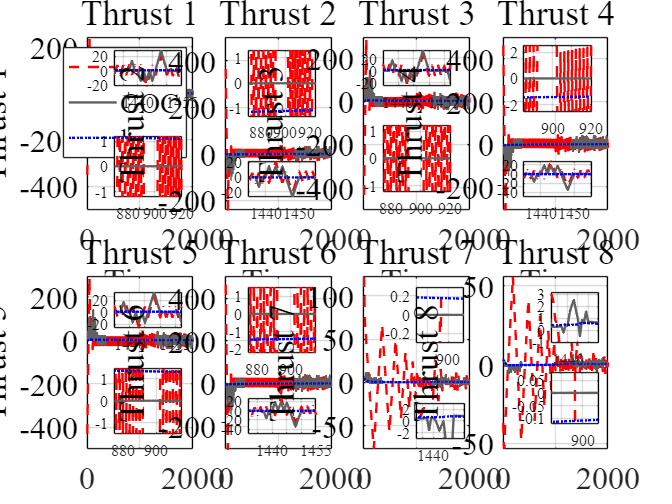

figure(4);
subplot(2,4,1);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 1');
xlabel('Time');
title('Thrust 1');
legend('SMC','COC','lqr');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h1 = axes('Position',[0.17 0.61 0.1 0.12]);
axes(h1);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[870 920],'ylim',[-1.2 1.2]);
set(gca,'FontName','Times New Roman');
grid on;

h9 = axes('Position',[0.17 0.83 0.1 0.07]);
axes(h9);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h9,'xlim',[1432 1455]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,2);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 2');
xlabel('Time');
title('Thrust 2');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h2 = axes('Position',[0.37 0.77 0.1 0.13]);
axes(h2);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h2,'xlim',[870 925],'ylim',[-1.3 1.3]);
set(gca,'FontName','Times New Roman');
grid on;

h10 = axes('Position',[0.37 0.61 0.1 0.07]);
axes(h10);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h10,'xlim',[1435 1455]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,3);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 3');
xlabel('Time');
title('Thrust 3');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h3 = axes('Position',[0.57 0.62 0.1 0.13]);
axes(h3);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h3,'xlim',[875 920],'ylim',[-1.2 1.2]);
set(gca,'FontName','Times New Roman');
grid on;

h11 = axes('Position',[0.57 0.83 0.1 0.07]);
axes(h11);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h11,'xlim',[1435 1457]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,4);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 4');
xlabel('Time');
title('Thrust 4');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h4 = axes('Position',[0.78 0.78 0.1 0.13]);
axes(h4);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h4,'xlim',[885 920],'ylim',[-2.5 2.5]);
set(gca,'FontName','Times New Roman');
grid on;

h12 = axes('Position',[0.78 0.61 0.1 0.07]);
axes(h12);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h12,'xlim',[1435 1455]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,5);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 5');
xlabel('Time');
title('Thrust 5');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h5 = axes('Position',[0.17 0.14 0.1 0.13]);
axes(h5);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h5,'xlim',[875 915],'ylim',[-1.5 1.5]);
set(gca,'FontName','Times New Roman');
grid on;

h13 = axes('Position',[0.17 0.35 0.1 0.07]);
axes(h13);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h13,'xlim',[1435 1457]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,6);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 6');
xlabel('Time');
title('Thrust 6');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h6 = axes('Position',[0.37 0.3 0.1 0.13]);
axes(h6);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h6,'xlim',[875 915],'ylim',[-2.2 1.5]);
set(gca,'FontName','Times New Roman');
grid on;

h14 = axes('Position',[0.37 0.14 0.1 0.07]);
axes(h14);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h14,'xlim',[1432 1455]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,7);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 7');
xlabel('Time');
title('Thrust 7');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h7 = axes('Position',[0.62 0.32 0.07 0.11]);
axes(h7);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h7,'xlim',[870 915],'ylim',[-0.3 0.3]);
set(gca,'FontName','Times New Roman');
grid on;

h15 = axes('Position',[0.62 0.13 0.07 0.07]);
axes(h15);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h15,'xlim',[1432 1455],'ylim',[-3 3]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,8);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 8');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Thrust 8');

h8 = axes('Position',[0.82 0.16 0.07 0.1]);
axes(h8);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h8,'xlim',[870 915],'ylim',[-0.12 0.08]);
set(gca,'FontName','Times New Roman');
grid on;

h16 = axes('Position',[0.82 0.32 0.07 0.1]);
axes(h16);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h16,'xlim',[1432 1455],'ylim',[-1 3.2]);
set(gca,'FontName','Times New Roman');
grid on;

% Change of Coordinated parameter

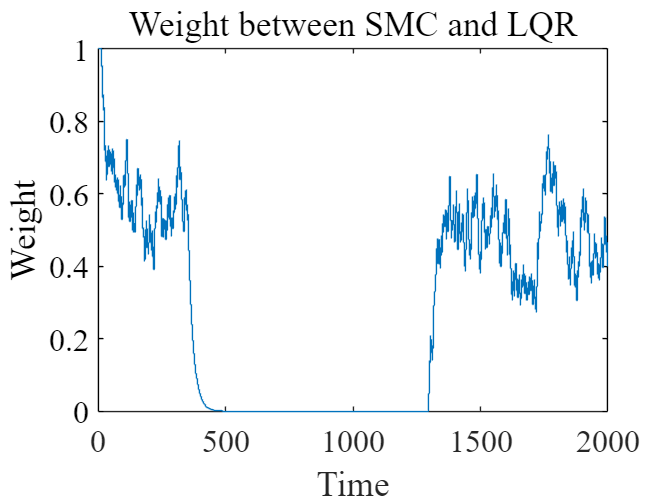

figure(5);
stairs(K_co_state_smooth(1,:));
ylabel('Weight');
xlabel('Time');
title('Weight between SMC and LQR');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

% Comparison of deviation separation

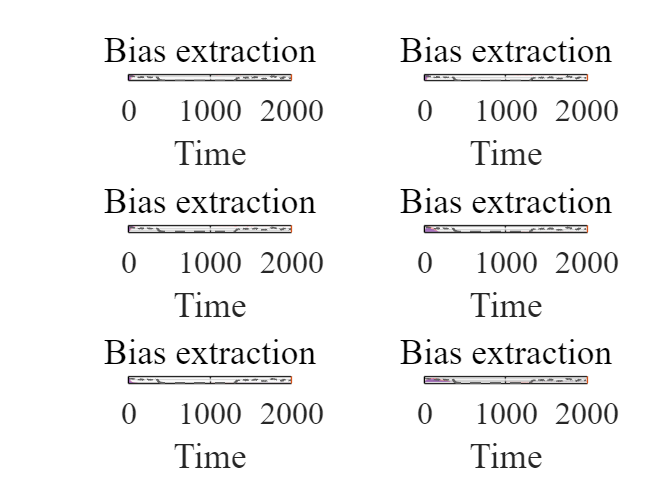

Time_bias_extraction = 1:1999;
Bound_bias_extraction = zeros(1,1999);
figure;
subplot(3,2,1);
yyaxis right;
plot(K_co_state_smooth(1,:),'--',Color=gray,LineWidth=1.5)
hold on;
yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(1,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(1,:),Bound_bias_extraction],'b');
grid on;
ylabel('X Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(3,2,3);
yyaxis right;
plot(K_co_state_smooth(2,:),'--',Color=gray,LineWidth=1.5)
hold on;
yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(2,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(2,:),Bound_bias_extraction],'b');
grid on;
ylabel('Y Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(3,2,5);
yyaxis right;
plot(K_co_state_smooth(3,:),'--',Color=gray,LineWidth=1.5)
hold on;
yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(3,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(3,:),Bound_bias_extraction],'b');
grid on;
ylabel('Z Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(3,2,2);
yyaxis right;
plot(K_co_state_smooth(4,:),'--',Color=gray,LineWidth=1.5)
hold on;
yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(4,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(4,:),Bound_bias_extraction],'b');
grid on;
ylabel('Phi Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(3,2,4);
yyaxis right;
plot(K_co_state_smooth(5,:),'--',Color=gray,LineWidth=1.5)
hold on;
yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(5,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(5,:),Bound_bias_extraction],'b');
grid on;
ylabel('Theta Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(3,2,6);
yyaxis right;
plot(K_co_state_smooth(6,:),'--',Color=gray,LineWidth=1.5)
hold on;
yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(6,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(6,:),Bound_bias_extraction],'b');
grid on;
ylabel('Psi Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

% Comparison on cost function

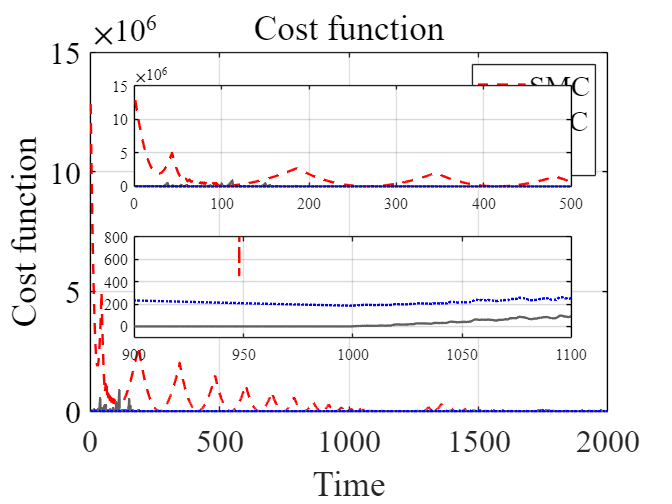

figure;
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(J_SMC_State,'--',Color='Red',LineWidth=1.5);
hold on;
plot(J_COC_State,'-',Color=gray,LineWidth=1.5);
hold on;
plot(J_LQR_State,':',Color='Blue',LineWidth=1.5);
grid on;
legend('SMC','COC','lqr');
ylabel('Cost function');
xlabel('Time');
title('Cost function');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h1 = axes('Position',[0.2 0.63 0.65 0.2]);
axes(h1);
plot(J_SMC_State,'--',Color='Red',LineWidth=1.5);
hold on;
plot(J_COC_State,'-',Color=gray,LineWidth=1.5);
hold on;
plot(J_LQR_State,':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[0 500]);
set(gca,'FontName','Times New Roman');
grid on;
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');

h2 = axes('Position',[0.2 0.33 0.65 0.2]);
axes(h2);
plot(J_SMC_State,'--',Color='Red',LineWidth=1.5);
hold on;
plot(J_COC_State,'-',Color=gray,LineWidth=1.5);
hold on;
plot(J_LQR_State,':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h2,'xlim',[900 1100],'ylim',[-100 800]);
set(gca,'FontName','Times New Roman');
grid on;
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');